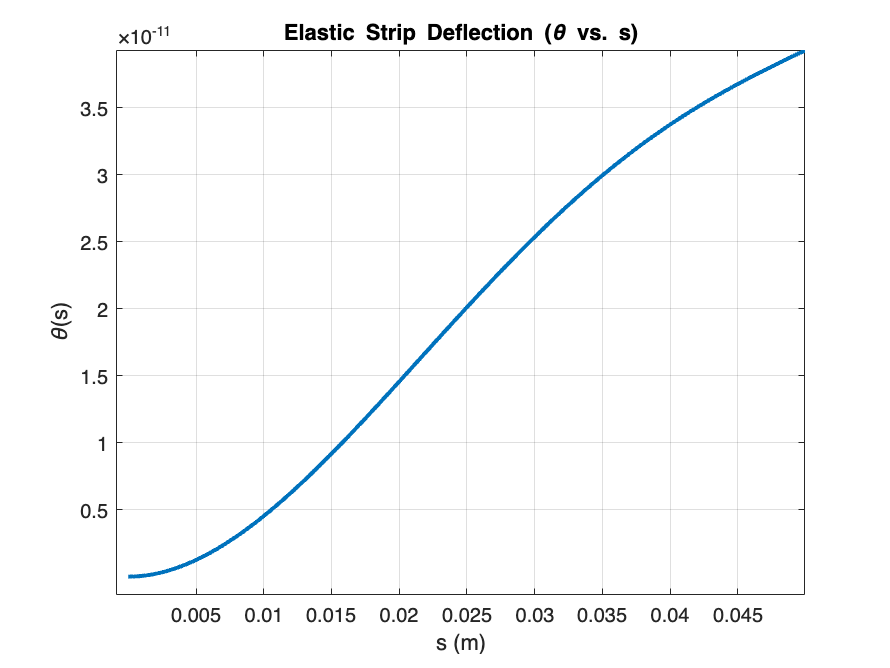

% Constants
B = 1.8e-5;  % Bending stiffness [Nm]
rho = 1000;  % Density of water [kg/m^3]
g = 9.81;    % Gravitational acceleration [m/s^2]
H = 0.02;    % Meniscus height [m]
L = 0.05;    % Length of strip [m]
gamma = 72e-3;  % Surface tension [N/m]
phi = pi / 4;  % Contact angle [radians]

% Capillary length
Lc = sqrt(gamma / (rho * g));  % Capillary length [m]

% Elastic wavenumber
k = (rho * g * H / B)^(1/4);

% Symbolic variables
syms C1 C2 C3 C4 s real

% General solution
theta = C1 * cos(k * s) + C2 * sin(k * s) + C3 * cosh(k * s) + C4 * sinh(k * s);

% Boundary conditions
% Clamped at s = 0
eq1 = subs(theta, s, 0) == 0;  % θ(0) = 0
eq2 = subs(diff(theta, s), s, 0) == 0;  % θ'(0) = 0

% Free at s = L
eq3 = subs(diff(theta, s, 2), s, L) == 0;  % θ''(L) = 0
eq4 = subs(diff(theta, s, 3), s, L) == Lc^2 * sin(phi);  % θ'''(L) = L_c^2 sin(φ)

% Solve for constants
constants = solve([eq1, eq2, eq3, eq4], [C1, C2, C3, C4]);

% Substitute the constants into the general solution
theta_sol = simplify(subs(theta, constants));

% Convert the symbolic solution into a MATLAB function
theta_numeric = matlabFunction(theta_sol);

% Discretize s and plot
s_vals = linspace(0, L, 500);  % Discretized strip length
theta_vals = theta_numeric(s_vals);  % Compute θ(s)

% Plot
figure;
plot(s_vals, theta_vals, 'LineWidth', 2);
xlabel('s (m)');
ylabel('\theta(s)');
title('Elastic Strip Deflection (\theta vs. s)');
grid on;